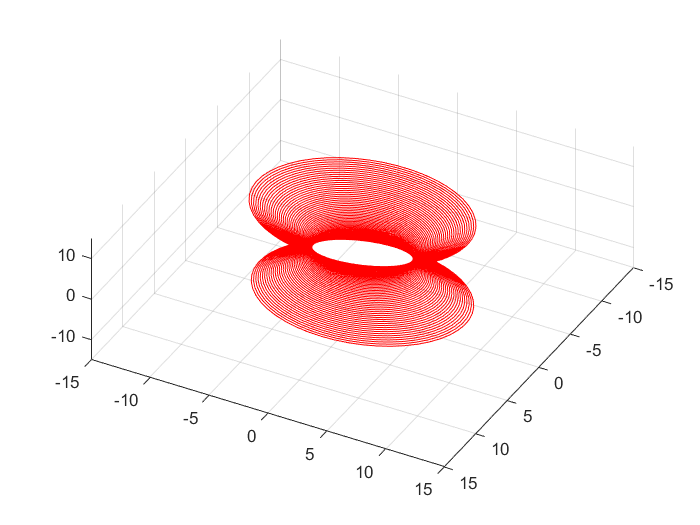

clc 
hold on
axis ([-15 15 -15 15 -15 15])
axis on 
grid on
view([0.4178 0.2247 0.8803])
a=3;b=4;c=5;
x=-a-5:a+5;
y=-b-5:b+5;
[X,Y]=meshgrid(x,y);
Z=zeros(size(X))+10; 
pic_num = 1;
for i=1:80
h=mesh(X,Y,Z);
k=sqrt(1+(Z(1)).^2/c.^2);%k的替换
Theta1=linspace(0,2*pi,50); 
X1=a*k.*cos(Theta1);%参数方程

                Y1=b*k.*sin(Theta1);

                Z1=zeros(length(X1))+Z(1); 

                g=plot3(X1,Y1,Z1,'r');

                Z=Z-1/4;

                F=getframe(gcf);

                I=frame2im(F);

                [I,map]=rgb2ind(I,256);%制作动图

                if pic_num == 1

                    imwrite(I,map,'test3.gif','gif', 'Loopcount',inf,'DelayTime',0.2);

                else

                    imwrite(I,map,'test3.gif','gif','WriteMode','append','DelayTime',0.2);

                end

                pic_num = pic_num + 1;

                delete(h);%删除上一个网格

                end